# NYT Puzzle Mania 2020 - 3D Word Hunt

Julian Bell, December 2020

This routine implements depth-limited search (maybe? I think?) of a graph to solve the 3D Word Hunt puzzle in the New York Times' 2020 Puzzle Mania special fold-out.

The original puzzle:

# 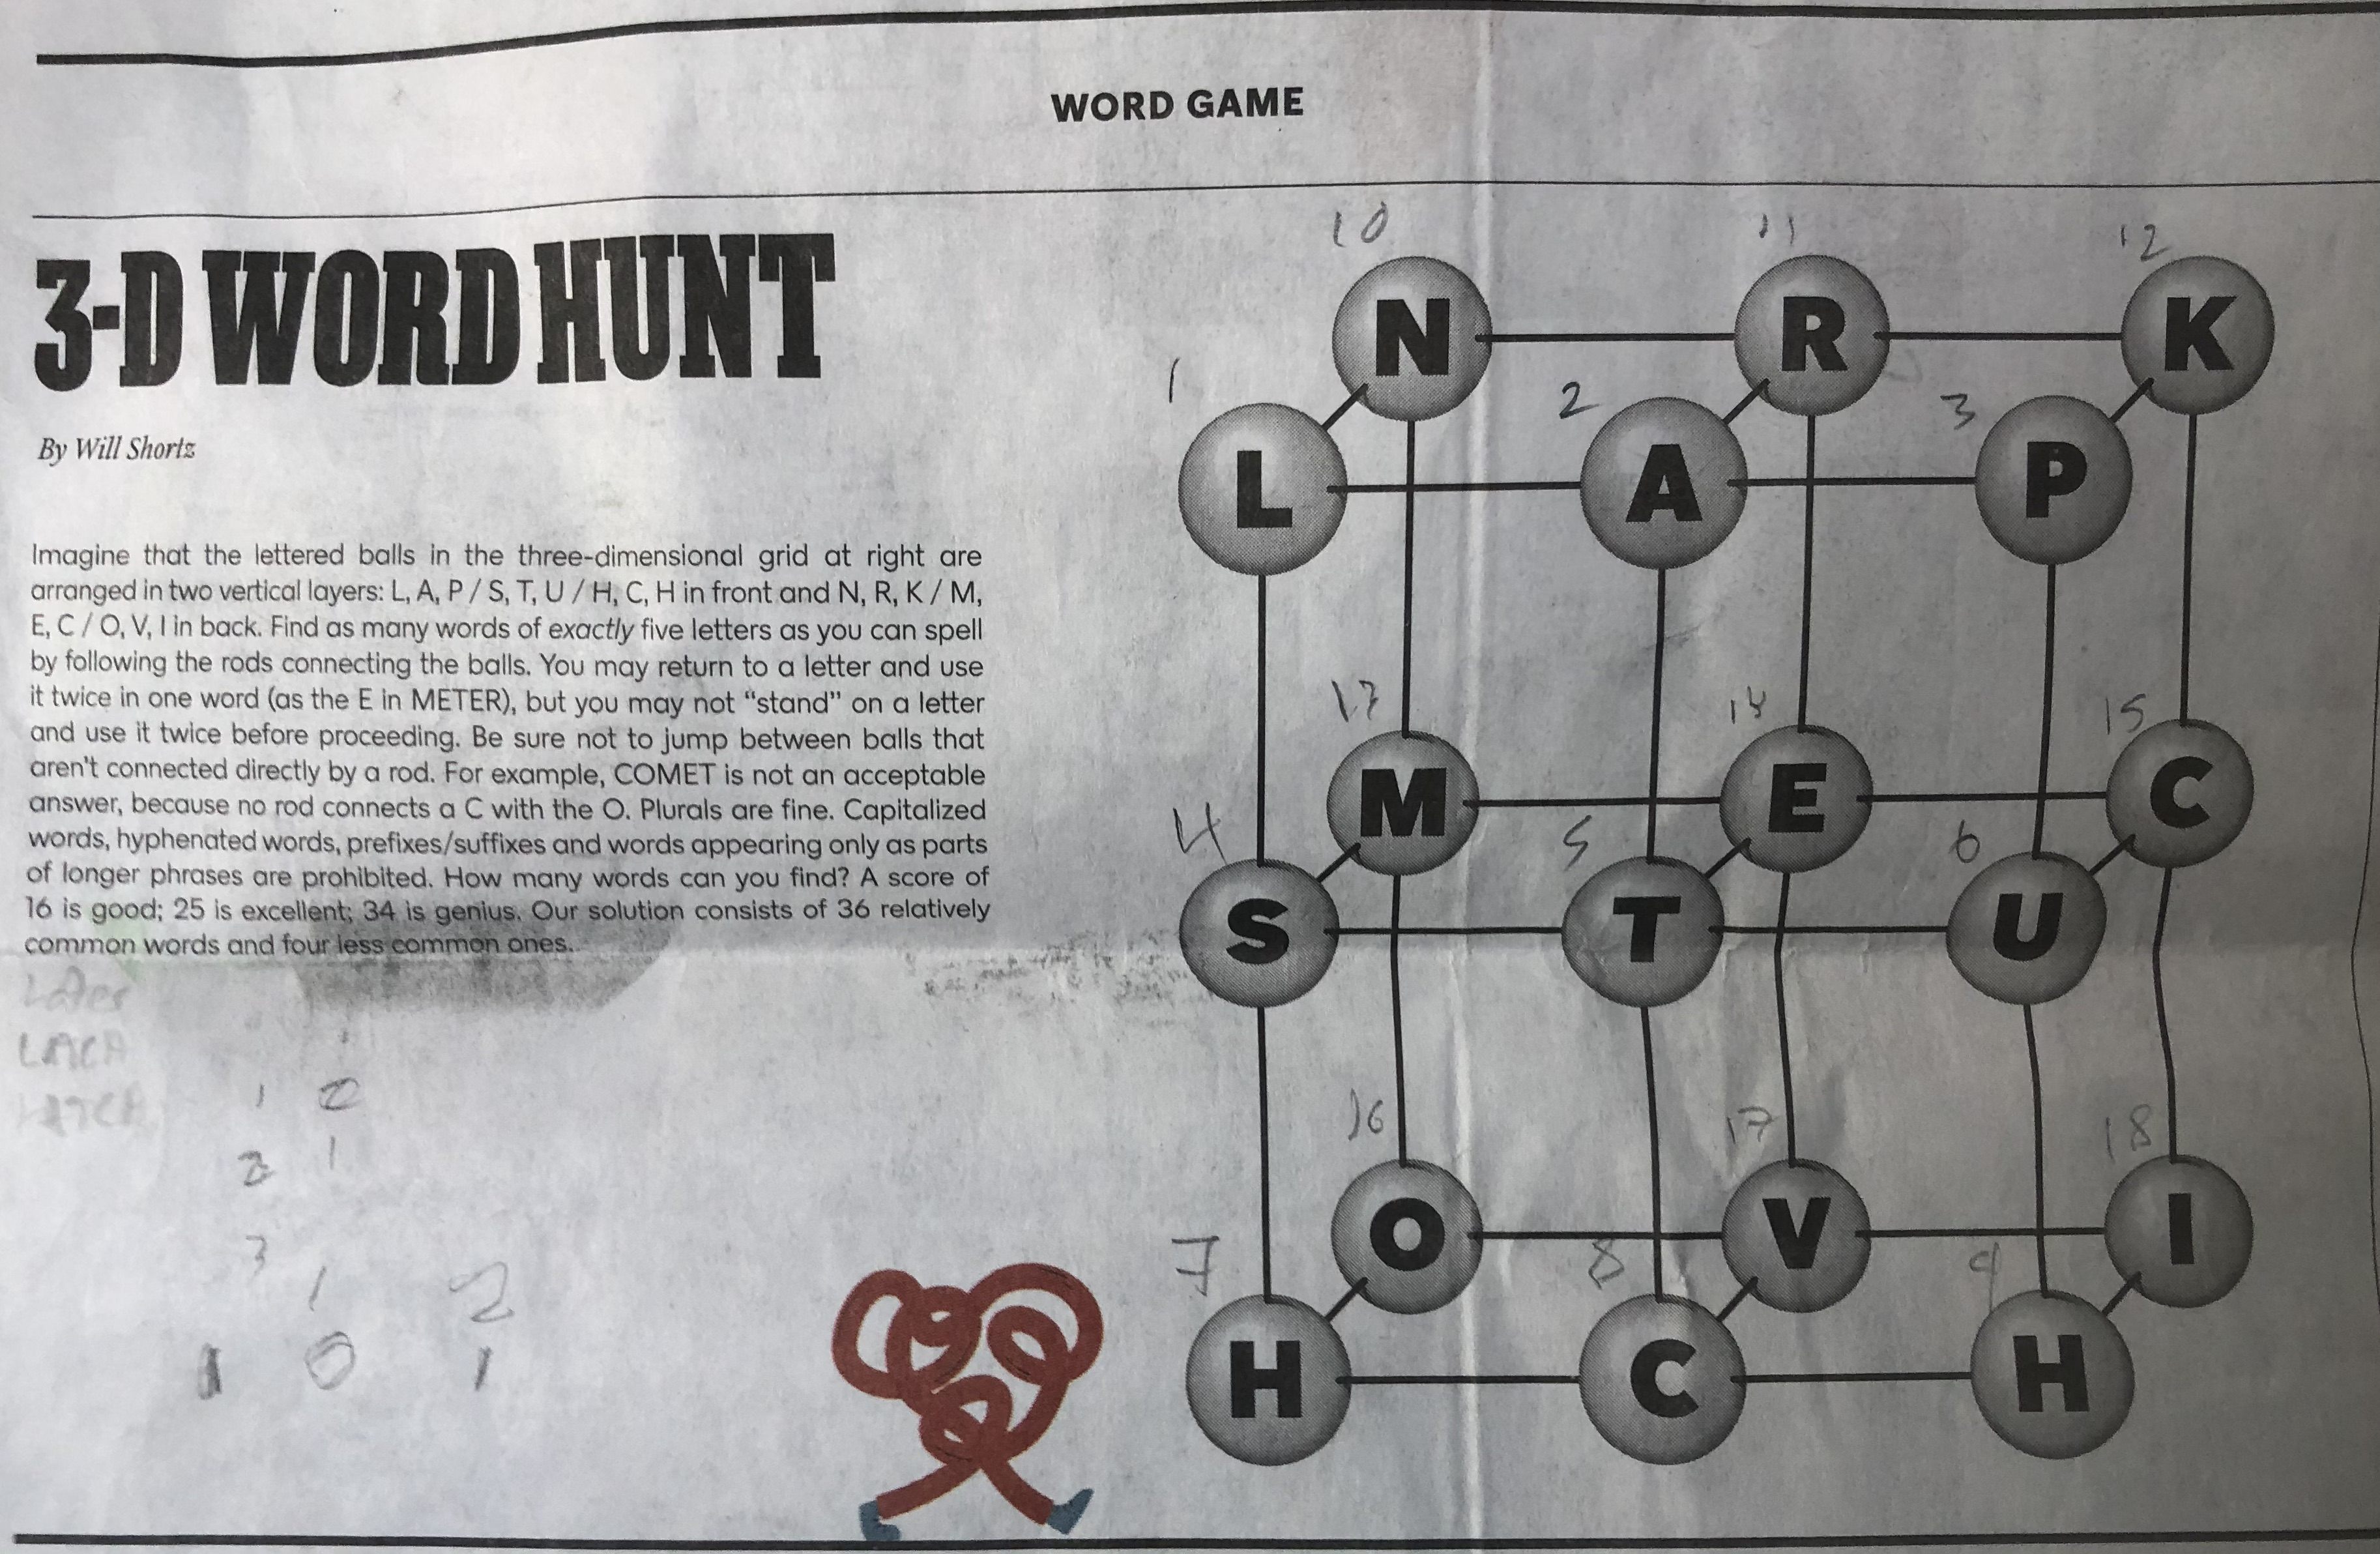

My findings:

1) MATLAB doesn't include a dictionary by default. WTF, Mathworks?

2) Depending on whose dictionary you refer to, there may be a lot more than 36 words in this graph - the random-free-from-the-Internet dictionary I use finds 81. A lot of these are preeeety questionable ("merer?"), so via visual inspection I narrowed these down to basically 36-ish like Will claims.

Finally, N

## Set up initial matrix representing connections

conn = zeros(18);
conn(1,[2 4 10]) = 1;
conn(2, [1 3 5 11]) = 1;
conn(3, [2 6 12]) = 1;
conn(4, [1 5 7 13]) = 1;
conn(5, [2 4 6 8 14]) = 1;
conn(6, [3 5 9 15]) = 1;
conn(7, [4 8 16]) = 1;
conn(8, [5 7 9 17]) = 1;
conn(9, [6 8 18]) = 1;
conn(10, [1 11 13]) = 1;
conn(11, [2 10 12 14]) = 1;
conn(12, [3 11 15]) = 1;
conn(13, [4 10 14 16]) = 1;
conn(14, [5 11 13 15 17]) = 1;
conn(15, [6 12 14 18]) = 1;
conn(16, [7 13 17]) = 1;
conn(17, [8 14 16 18]) = 1;
conn(18, [9 15 17]) = 1;


## Create graph

% Generate graph
G = graph(conn);

% Set names
names = {'l','a','p','s','t','u','h','c','h','n','r','k','m','e','c','o','v','i'};
G.Nodes.Character = names';


## Traverse graph and generate paths

% Setup
[numNodes, ] = size(G.Nodes); 
pathList= []; % Empty struct to hold possible paths
depth = 5; % Depth to search for

% Generate paths
for n = 1:numNodes
    curPath = dls(G,n,depth-1);
    pathList = [pathList;curPath];
    curPath = [];
end


## Convert paths to words

wordList = cell(length(pathList),1)

wordList = 3650×1 cell array
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}
    {0×0 double}


for n = 1:length(pathList)
    word = "";
    for m = 1:depth
        idx = pathList(n,m);
        word = strcat(word,G.Nodes(idx,1).Character{:});
    end
    wordList{n} = word;
end


## Check whether words are real

% You can't do this in MATLAB without a package? ABSURD. You stink on ice,
% Mathworks.

% Using text file of English words from here https://github.com/dwyl/english-words
% Import text file
fullDict = readcell("words_alpha.txt");

% Select out only elements with length == possible word length
L = cellfun(@length,fullDict)  ;  % GEt length of each cell array 
subDict = fullDict(L==depth);

% Check words against dictionary
realWords = {}


realWords =

  0×0 empty cell array



for n = 1:length(wordList)
    if any(strcmp(wordList{n},subDict))
        realWords = [realWords;wordList{n}];
    end
end

% Remove duplicates
realUniqueWords = unique(realWords);